opts = detectImportOptions('fxdata.csv');
T = readtable('fxdata.csv',opts);

X = T;
Xc = table2cell(X);
X_transposed = Xc';

A = X_transposed;
tickers = A(1,:);
data = A(2:378,:);

data = cell2mat(data);

data = fillmissing(data, "previous",1);

daily_returns = zeros(376, 58); % Initialization

% Compute the daily returns
for j =1:58
    for i=1:376
        daily_returns(i,j) = (data(i+1,j) - data(i,j)) / data(i,j);
    end
end

% Compute the correlation matrix of daily returns
correlation = corrcoef(daily_returns);

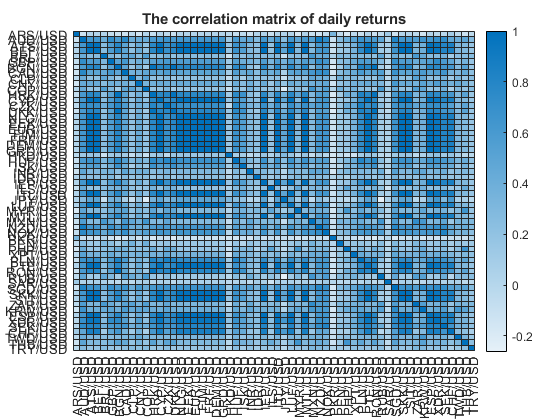

figure;
h = heatmap(correlation);
h.XDisplayLabels = string(tickers);
h.YDisplayLabels = string(tickers);
title("The correlation matrix of daily returns");

[temp, order] = sort(correlation(1,:));
answer = correlation(:,order);
[temp, order] = sort(answer(:,1));
answer2 = answer(:,order);

MeanCorrMatPerm=mean(correlation);
[sortedCorr, indPerm]=sort(MeanCorrMatPerm,'descend');
sorted = correlation(indPerm,indPerm);
sort_title= tickers(:,indPerm );

figure;
h = heatmap(sorted,"Colormap",turbo);
h.XDisplayLabels = string(sort_title);
h.YDisplayLabels = string(sort_title);
title("The correlation matrix of daily returns");

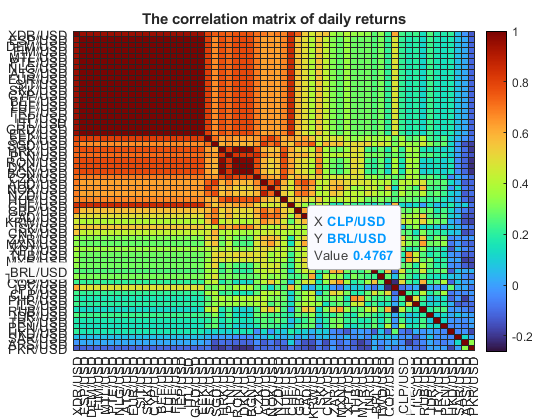

x = string(zeros(58*58, 1));
y = string(zeros(58*58, 1));
value = zeros(58*58, 1);

index = 1;
for i=1:58
    for j = 1:58        
        x(index) = erase(sort_title(i), '/USD');
        y(index) = erase(sort_title(j), '/USD');
        value(index) = sorted(i,j);  
        index = index + 1;
    end
end

T1 = array2table(x,'VariableNames',{'x'});
T1.y = y;
T1.value = value;

writetable(T1,'myData.csv','Delimiter',',')

for i= 1:length(sort_title)
    sort_title(i) = erase(sort_title(i), '/USD');
end

sorted(1:1+size(sorted,1):end) = 0;

OutputNetwork(sorted,sort_title);

T = array2table(data)

T = 377×58 table
    data1     data2     data3     data4     data5      data6     data7     data8     data9     data10    data11    data12    data13     data14    data15    data16    data17    data18     data19    data20    data21    data22    data23    data24    data25    data26    data27    data28     data29    data30    data31    data32    data33    data34     data35    data36    <s

T.Properties.VariableNames = tickers

T = 377×58 table
    ARS/USD    AUD/USD    ATS/USD    BEF/USD    BRL/USD    GBP/USD    BGN/USD    CAD/USD    CLP/USD    CNY/USD    COP/USD    HRK/USD    CYP/USD    CZK/USD    DKK/USD    NLG/USD    EEK/USD    EUR/USD    FIM/USD    FRF/USD    DEM/USD    GRD/USD    HKD/USD    HUF/USD    ISK/USD    INR/USD    IDR/USD    IEP/USD    ILS/USD    ITL/USD    JPY/USD    LUF/USD    MYR/USD    MTL/USD    MXN/USD   

writetable(T,'pythonData.csv','Delimiter',',')

threshold = 0.4;
sorted(sorted<0.4)  = 0;
OutputNetwork(sorted,sort_title);